Modelo del robot ABB IRB 2400 utilizando Robotics System Toolbox de Matlab. 

L0=6.15;  
L1=1.00;
L2=7.05;
L3=1.35;
L4=7.55;
L5=0.85;

robotabb_rst=rigidBodyTree;

dhparams=[  0     0     0     0  ;
           0.1*L1   pi/2    0     0  ;
           0.1*L2     0     0     0  ;
           0.1*L3   pi/2   0.1*L4     0  ;
            0  -pi/2    0     0  ;
            0   pi/2   0.1*L5     0];

link1=rigidBody('link1');
link1.Joint=rigidBodyJoint('art1','revolute');
link2=rigidBody('link2');
link2.Joint=rigidBodyJoint('art2','revolute');
link3=rigidBody('link3');
link3.Joint=rigidBodyJoint('art3','revolute');
link4=rigidBody('link4');
link4.Joint=rigidBodyJoint('art4','revolute');
link5=rigidBody('link5');
link5.Joint=rigidBodyJoint('art5','revolute');
link6=rigidBody('link6');
link6.Joint=rigidBodyJoint('art6','revolute');

link1.Joint.PositionLimits=[deg2rad(-180) deg2rad(180)];
link2.Joint.PositionLimits=[deg2rad(-100) deg2rad(110)];
link3.Joint.PositionLimits=[deg2rad(-60) deg2rad(65)];
link4.Joint.PositionLimits=[deg2rad(-200) deg2rad(200)];
link5.Joint.PositionLimits=[deg2rad(-120) deg2rad(120)];
link6.Joint.PositionLimits=[deg2rad(-400) deg2rad(400)];

setFixedTransform(link1.Joint,dhparams(1,:),'mdh');
setFixedTransform(link2.Joint,dhparams(2,:),'mdh');
setFixedTransform(link3.Joint,dhparams(3,:),'mdh');
setFixedTransform(link4.Joint,dhparams(4,:),'mdh');
setFixedTransform(link5.Joint,dhparams(5,:),'mdh');
setFixedTransform(link6.Joint,dhparams(6,:),'mdh');

addBody(robotabb_rst,link1,'base')
addBody(robotabb_rst,link2,'link1')
addBody(robotabb_rst,link3,'link2')
addBody(robotabb_rst,link4,'link3')
addBody(robotabb_rst,link5,'link4')
addBody(robotabb_rst,link6,'link5')

figure(1)
showdetails(robotabb_rst)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        link1         art1     revolute             base(0)   link2(2)  
   2        link2         art2     revolute            link1(1)   link3(3)  
   3        link3         art3     revolute            link2(2)   link4(4)  
   4        link4         art4     revolute            link3(3)   link5(5)  
   5        link5         art5     revolute            link4(4)   link6(6)  
   6        link6         art6     revolute            link5(5)   
--------------------


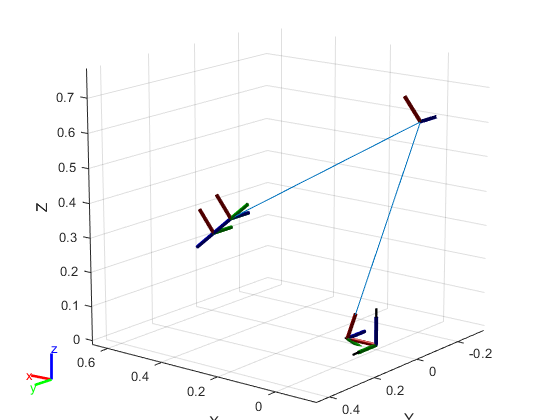

show(robotabb_rst,config);
xlim([-0.140 0.656])
ylim([-0.336 0.459])
zlim([-0.013 0.783])
view([-142.069 14.790])

**Cinemática inversa**

Para la solución de la cinemática inversa se partió primero de la cinemática directa. Se definió un conjunto de ángulos $q$ y luego se encontró cual era la posición y orientación del efector final. Luego se realizó la cinemática inversa para dicha POSE y como resultado se obtuvieron los valores de $q$ que dan la misma POSE, sin embargo los valores de $q$ pueden ser diferentes cuando la POSE está dentro del espacio de trabajo diestro. Esto implica que, debido a la multiplicidad de resultados, Matlab encuentre un resultado que dé dicha POSE y que sea diferente de los valores de $q$ del que partió. 

**Procedimiento**

Se encuentra la pose de los 7 puntos de calibración y de 4 puntos adicionales, definidos por nosotros. Luego, por medio de la función *fun_pose*, se encuentra la pose para un conjunto de ángulos $q$. Estos datos son luego utilizados en la función *cinematicaInversa* para encontrar los valores $q$ que den dicha pose. La funcion del Toolbox de Robotics es *ik=inverse kinematics* y toma como valores semilla la posición de home del robot. Cuando existen más de una respuesta para una misma pose, se pueden encontrar al variar los valores semilla. Este proceso es iterativo, de prueba y error. 

q_cal=[0,0,0,0,0,0;
       0,0,-60,0,0,0;
       0,0,65,0,0,0;
       0,110,-60,0,0,0;
       0,110,18.3,0,0,0;
       0,-100,-60,0,0,0;
       0,-100,65,0,0,0;];


q=[q_cal;
   45,-30,-60,0,45,90;
   135,-60,15,30,60,45;
   -45,60,30,60,0,-135;
   120,90,45,135,-60,90];

La cinemática inversa para las 11 POSE's son

POSE #1: 


    3.1416         0         0    0.9400   -0.0000   -0.8400



Angulos q resultantes


     0     0     0     0     0     0



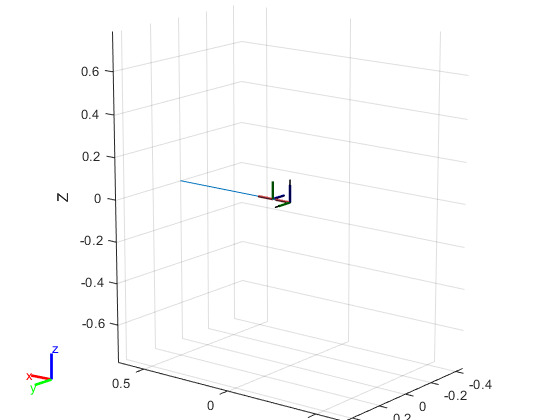

POSE #2: 


    3.1416   -1.0472   -0.0000    0.1450   -0.0000   -0.5369



Angulos q resultantes


   -0.0000    0.0000  -60.0000   -0.0000   -0.0000   -0.0000



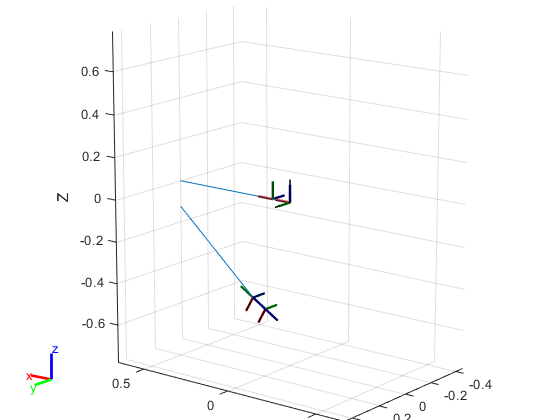

POSE #3: 


    3.1416    1.1345    0.0000    1.6234   -0.0000   -0.2326



Angulos q resultantes


   -0.0000   -0.0000   65.0000   -0.0000    0.0000    0.0000



POSE #4: 


    3.1416    0.8727    0.0000    0.5891   -0.0000    0.2260



Angulos q resultantes


   -0.0000  110.0000  -60.0000    0.0000    0.0000    0.0000



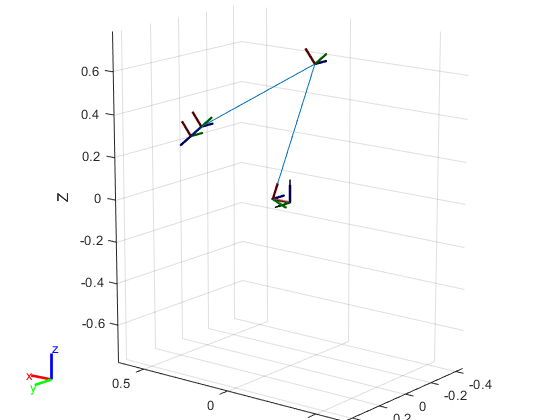

POSE #5: 


    0.0000    0.9023    3.1416    0.4344    0.0000    1.2890



Angulos q resultantes


    0.0000  110.0000   18.3000    0.0000    0.0000   -0.0000



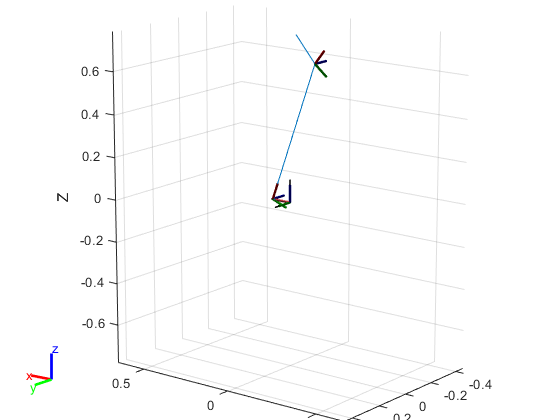

POSE #6: 


    0.0000   -0.3491   -3.1416   -0.4366   -0.0000    0.0489



Angulos q resultantes


    0.0000 -100.0000  -60.0000    0.0000    0.0000    0.0000



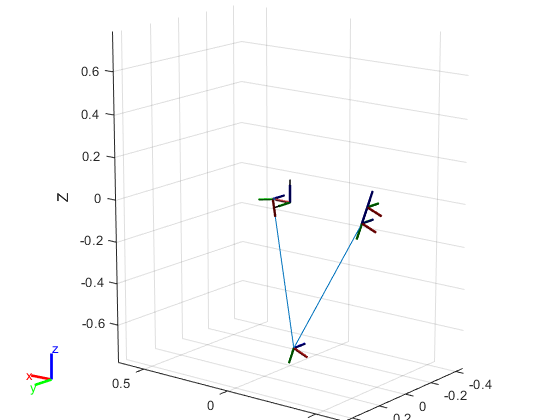

POSE #7: 


    3.1416   -0.6109   -0.0000   -0.3936   -0.0000   -1.4598



Angulos q resultantes


   -0.0000 -100.0000   65.0000    0.0000   -0.0000   -0.0000



POSE #8: 


    2.5261   -0.5236    0.6155   -0.0739   -0.0739   -0.5476



Angulos q resultantes


   45.0000  -30.0000  -60.0000    0.0000   45.0000   90.0000



POSE #9: 


   -2.6877    0.1822   -1.2868    0.0054    0.0466   -1.3150



Angulos q resultantes


  -45.0000  -61.4690   15.3304  -40.0678   42.2757  -87.0015



POSE #10: 


    1.5708    0.7854    0.2618    0.9139   -0.9139    0.7455



Angulos q resultantes


  -45.0000   60.0000   30.0000  -36.1034    0.0000  -38.8966



POSE #11: 


    0.4449   -0.5128   -2.9976   -0.3109    0.4344    1.4012



Angulos q resultantes


  120.0000   90.0000   45.0000  -45.0000   60.0000  270.0000



for m=1:11
V_pose_P2=fun_pose(q(m,1:6),robotabb_rst);
disp("POSE #"+m+": ")
disp(V_pose_P2)
[configSoln_P2,solnInfo_P2,q_resul] = cinematicaInversa(V_pose_P2,robotabb_rst);
tform2 = getTransform(robotabb_rst,configSoln_P2,'link6','base'); %Es la MTH del EF en la posición random.  
disp("Angulos q resultantes")
disp(q_resul')
disp(" ")
figure()
show(robotabb_rst,configSoln_P2);
xlim([-0.656 0.656])
ylim([-0.459 0.459])
zlim([-0.783 0.783])
view([-142.069 14.790])

end

Funciones *fun_pose* y *cinematicaInversa.*

function [POSE]=fun_pose(q,robotabb_rst)
    config = homeConfiguration(robotabb_rst);
    config(1).JointPosition = deg2rad(q(1));
    config(2).JointPosition = deg2rad(q(2));
    config(3).JointPosition = deg2rad(q(3));
    config(4).JointPosition = deg2rad(q(4));
    config(5).JointPosition = deg2rad(q(5));
    config(6).JointPosition = deg2rad(q(6));
    tform = getTransform(robotabb_rst,config,'link6','base'); %Es la MTH del EF en la congiguracion config.  
    angulos=tr2rpy(tform);
    POSE=[angulos(1),angulos(2),angulos(3),tform(1,4),tform(2,4),tform(3,4)]; % Roll Pitch Yaw X Y 
end


function [configSoln,solnInfo,q]=cinematicaInversa(V_pose,robotabb_rst)

q=zeros(6,1);
tform_t=transl(V_pose(4),V_pose(5),V_pose(6));
tform_r=trotx(V_pose(1))*troty(V_pose(2))*trotz(V_pose(3));
tform=[tform_r(1:3,1:3),tform_t(1:3,4);0,0,0,1];


ik = inverseKinematics('RigidBodyTree',robotabb_rst);
weights = [0.1 0.1 0.1 0.1 0.1 0.1];
initialguess = robotabb_rst.homeConfiguration;

[configSoln,solnInfo] = ik('link6',tform,weights,initialguess);

for i=1:6
    q(i)=rad2deg(configSoln(i).JointPosition(1));
end

end
